clc
clear
CAR.m = 1675; % kg
CAR.L = 2.675; % distance [m]
CAR.g = 9.81; %Gravity constant
CAR.steeringRatio = 15.9;
        
front_ratio_1 = 0.37;
front_ratio_2 = 0.63;
front_ratio_3 = 0.47;


## Task1.2 Understeering gradients

front_ratio = front_ratio_1;
[Cf1,Cr1] = calCfCr(front_ratio, CAR);
[lf1,lr1] = callflr(front_ratio, CAR);
Ku1 = calKu(lf1,lr1, Cf1, Cr1, CAR)

Ku1 = 6.9965e-07

front_ratio = front_ratio_2;
[Cf2,Cr2] = calCfCr(front_ratio, CAR);
[lf2,lr2] = callflr(front_ratio, CAR); 
Ku2 = calKu(lf2, lr2, Cf2, Cr2, CAR)

Ku2 = -6.9965e-07

front_ratio = front_ratio_3;
[Cf3,Cr3] = calCfCr(front_ratio, CAR);
[lf3,lr3] = callflr(front_ratio, CAR); 
Ku3 = calKu(lf3, lr3, Cf3, Cr3, CAR)

Ku3 = 1.5928e-07

## Task1.3 Critical/Characteristic speed

% vx_crit_1 = calVxcrit(Ku1, CAR)
vx_crit_2 = calVxcrit(Ku2, CAR)

vx_crit_2 = 47.7766

% vx_crit_3 = calVxcrit(Ku3, CAR)
vx_char_1 = calVxchar(Ku1, CAR)

vx_char_1 = 47.7766

% vx_char_2 = calVxchar(Ku2, CAR)
vx_char_3 = calVxchar(Ku3, CAR)

vx_char_3 = 100.1318

## Task 1.4: Steering wheel angle for one certain operating point

vx = 100/3.6;
ay = 4;
steer1 = calSteer_certain_point(vx, ay, Ku1, CAR)*CAR.steeringRatio

steer1 = 0.2950

rad2deg(steer1)

ans = 16.9035

steer2 = calSteer_certain_point(vx, ay, Ku2, CAR)*CAR.steeringRatio

steer2 = 0.1460

rad2deg(steer2)

ans = 8.3626

steer3 = calSteer_certain_point(vx, ay, Ku3, CAR)*CAR.steeringRatio

steer3 = 0.2375

rad2deg(steer3)

ans = 13.6053

## Task1.5 Steering wheel angle for varying operating point

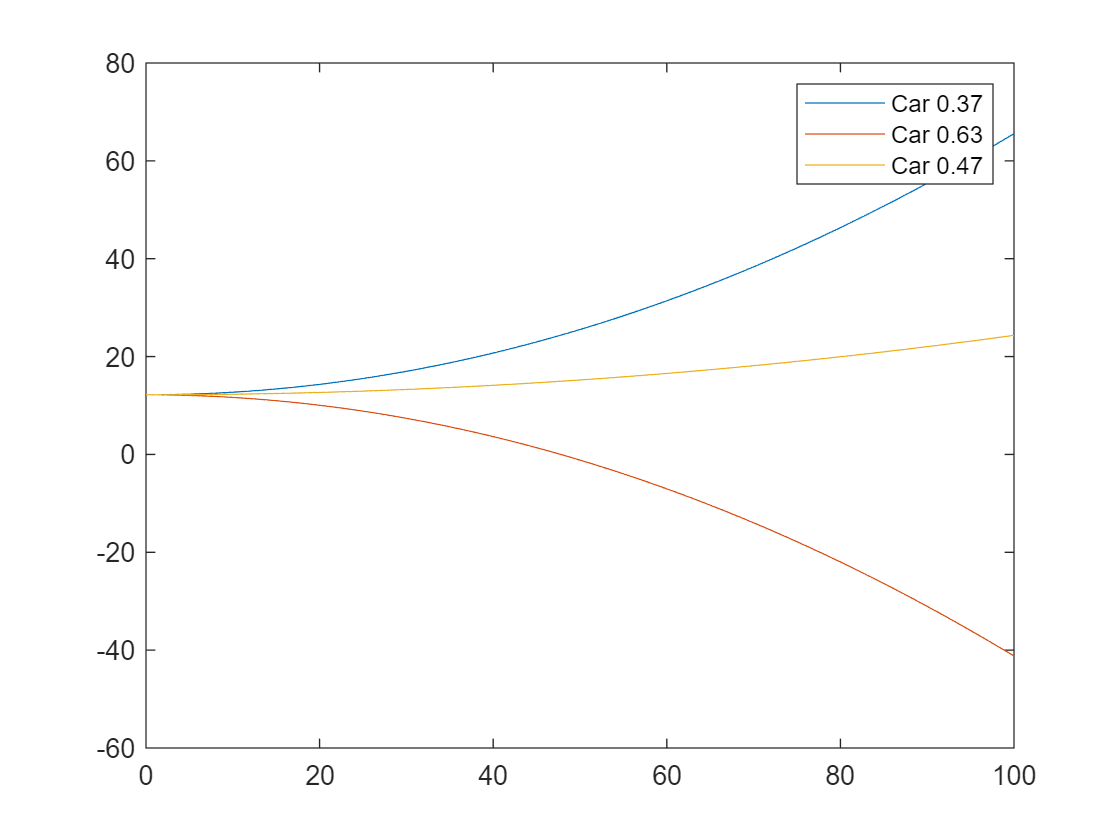

Rp = 200;
vx = 0:0.1:100;
steers1 = calSteer(vx, Rp, Ku1, CAR);
steers2 = calSteer(vx, Rp, Ku2, CAR);
steers3 = calSteer(vx, Rp, Ku3, CAR);

figure
plot(vx, steers1)
hold on
plot(vx, steers2)
plot(vx, steers3)
legend("Car 0.37", "Car 0.63", "Car 0.47")

function [lf,lr] = callflr(front_ratio, CAR)
    lf = front_ratio * CAR.L;   
    lr = (1-front_ratio) * CAR.L;
end

function [Cf,Cr] = calCfCr(front_ratio, CAR)
    c0 = 30.7;
    c1 = -0.00235;

    F_fz1 = CAR.m * CAR.g * (1-front_ratio)/2;  % Fz per wheel
    F_fr1 = CAR.m * CAR.g * front_ratio/2;

    Cf = (c0*F_fz1 + c1 * F_fz1^2)*2;
    Cr = (c0*F_fr1 + c1 * F_fr1^2)*2;
end

function Ku = calKu(lf, lr, Cf, Cr, CAR)
    Ku = ((Cr*lr)-(Cf*lf))/(Cf*Cr*CAR.L);
end

function vx_crit = calVxcrit(Ku, CAR)
    vx_crit = sqrt(CAR.L/(-Ku*CAR.m));
end

function vx_char = calVxchar(Ku, CAR)
    vx_char = sqrt(CAR.L/(Ku*CAR.m));
end

function steer = calSteer_certain_point(vx, ay, Ku, CAR)
    steer = ay*(CAR.L + Ku*CAR.m*vx^2)/vx^2;
end

function steer = calSteer(vx, Rp, Ku, CAR)
    steer = rad2deg((CAR.L/Rp + Ku*(CAR.m.*vx.^2)/Rp)*CAR.steeringRatio);
end